# Leloup-Goldbeter Model

# Parameters

53 in total

p = struct();
p.k_1 = 0.4;
p.k_2 = 0.2;
p.k_3 = 0.4;
p.k_4 = 0.2;
p.k_5 = 0.4;
p.k_6 = 0.2;
p.k_7 = 0.5;
p.k_8 = 0.1;
p.K_AP = 0.7;
p.K_AC = 0.6;
p.K_IB = 2.2;
p.k_dmb = 0.01;
p.k_dmc = 0.01;
p.k_dmp = 0.01;
p.k_dn = 0.01;
p.k_dnc = 0.12;
p.K_d = 0.3;
p.K_dp = 0.1;
p.K_p = 0.1;
p.K_mB = 0.4;
p.K_mC = 0.4;
p.K_mP = 0.31;
p.k_sB = 0.12;
p.k_sC = 1.6;
p.k_sP = 0.6;
p.m = 2;
p.n = 4;
p.V_1B = 0.5;
p.V_1C = 0.6;
p.V_1P = 0.4;
p.V_1PC = 0.4;
p.V_2B = 0.1;
p.V_2C = 0.1;
p.V_2P = 0.3;
p.V_2PC = 0.1;
p.V_3B = 0.5;
p.V_3PC = 0.4;
p.V_4B = 0.2;
p.V_4PC = 0.1;
p.V_phos = 0.4;
p.v_dBC = 0.5;
p.v_dBN = 0.6;
p.v_dCC = 0.7;
p.v_dIN = 0.8;
p.v_dPC = 0.7;
p.v_dPCC = 0.7;
p.v_dPCN = 0.7;
p.v_mB = 0.8;
p.v_mC = 1.0;
p.v_mP = 1.1;
p.v_sB = 1.0;
p.v_sC = 1.1;
p.current_v_sP = 1.5;

p_fields = {'k_1', 'k_2', 'k_3', 'k_4', 'k_5', 'k_6', 'k_7', 'k_8', ...
              'K_AP', 'K_AC', 'K_IB', 'k_dmb', 'k_dmc', 'k_dmp', 'k_dn', 'k_dnc', ...
              'K_d', 'K_dp', 'K_p', 'K_mB', 'K_mC', 'K_mP', 'k_sB', 'k_sC', ...
              'k_sP', 'm', 'n', 'V_1B', 'V_1C', 'V_1P', 'V_1PC', 'V_2B', ...
              'V_2C', 'V_2P', 'V_2PC', 'V_3B', 'V_3PC', 'V_4B', 'V_4PC', 'V_phos', ...
              'v_dBC', 'v_dBN', 'v_dCC', 'v_dIN', 'v_dPC', 'v_dPCC', 'v_dPCN', ...
              'v_mB', 'v_mC', 'v_mP', 'v_sB', 'v_sC', 'current_v_sP'};

p_array = zeros(length(p_fields), 1);

for i = 1:length(p_fields)
    p_array(i) = p.(p_fields{i});
end

# Init

y: 16 vars

y = struct();
y.M_P = 1.5;
y.M_C = 1.3;
y.M_B = 3.3;

y.P_C = 0;
y.C_C = 0;
y.P_CP = 0;
y.C_CP = 0;

y.PC_C = 0;
y.PC_N = 0;
y.PC_CP = 0;
y.PC_NP = 0;

y.B_C = 0;
y.B_CP = 0;
y.B_N = 0;
y.B_NP = 0;

y.I_N = 0;

y_fields = {'M_P', 'M_C', 'M_B', 'P_C', 'C_C', 'P_CP', 'C_CP', ...
            'PC_C', 'PC_N', 'PC_CP', 'PC_NP', 'B_C', 'B_CP', 'B_N', 'B_NP', 'I_N'};

y_array = zeros(length(y_fields), 1);

for i = 1:length(y_fields)
    y_array(i) = y.(y_fields{i});
end

# Simulation

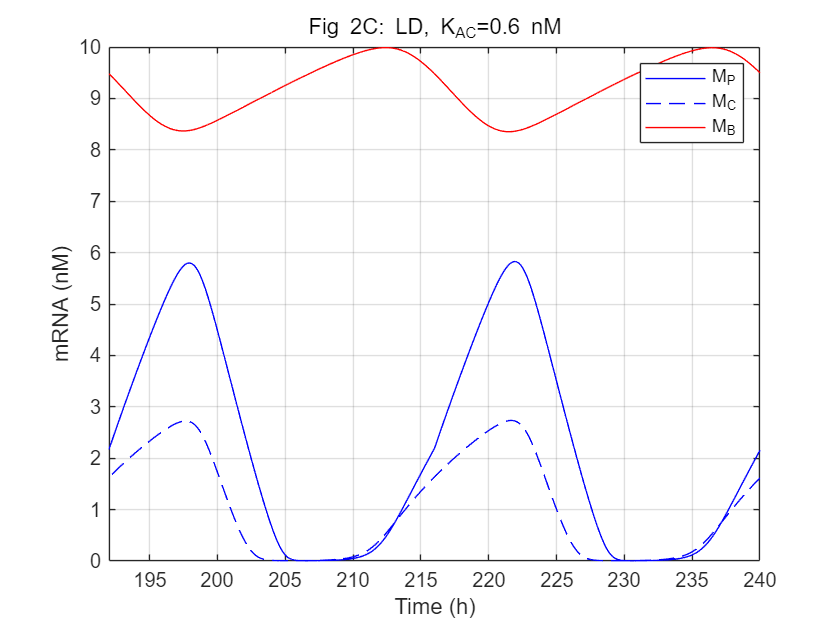

% -----------------------------------------------------------------
%           参数、初值、常驻代码 —— 你原来的部分保持不变
% -----------------------------------------------------------------
tspan = [0 240];      % 建议跑 10 天，等它稳定锁相
options = odeset('RelTol',1e-8,'AbsTol',1e-10);
% -----------------------------------------------------------------

% ===========  Fig 2C  (K_AC = 0.6  nM) ===========
[t2C, y2C] = ode45(@LG, tspan, y_array, options, p_array);

% ===========  Fig 2D  (K_AC = 0.4  nM) ===========
p_array_F2D = p_array;
p_array_F2D(10) = 0.4;         % 第 10 个元素正好是 K_AC
[t2D, y2D] = ode45(@LG, tspan, y_array, options, p_array_F2D);

% -----------   后面算总蛋白、画图   ------------
% 提示：你可以把下面这几行封成函数，避免重复
draw_mRNA(t2C, y2C, 'Fig 2C: LD, K_{AC}=0.6 nM');

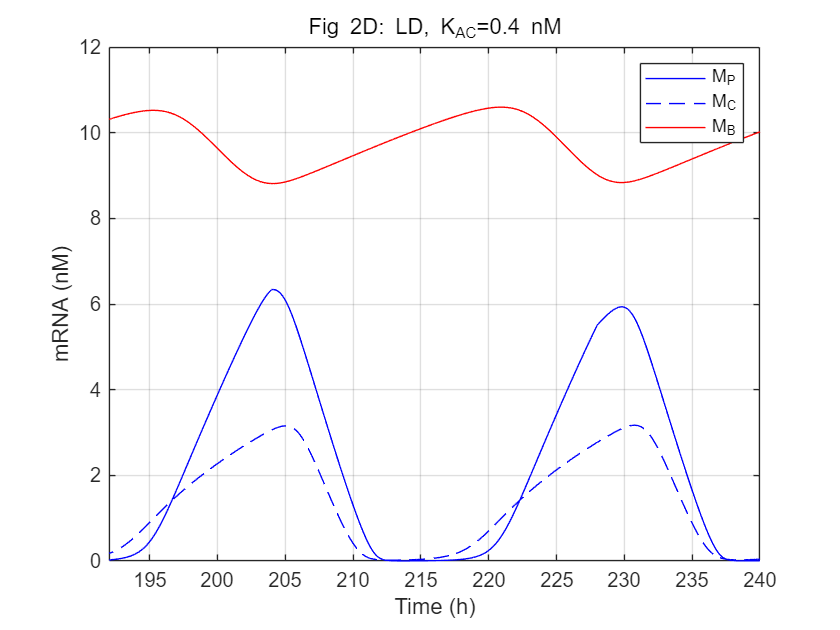

draw_mRNA(t2D, y2D, 'Fig 2D: LD, K_{AC}=0.4 nM');


% ===== 函数：只画三条 mRNA 曲线，最后 48 h =====
function draw_mRNA(t, y, ttl)
    figure;
    plot(t, y(:,1), 'b-',  ... % Per mRNA
         t, y(:,2), 'b--', ... % Cry mRNA
         t, y(:,3), 'r-');     % Bmal1 mRNA
    xlabel('Time (h)'); ylabel('mRNA (nM)');
    title(ttl); legend('M_P','M_C','M_B');
    xlim([t(end)-48, t(end)]); % 只看最后两天
    grid on;
end
